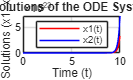

syms x1(t) x2(t)
 A = [1 2; 3 4];
 B = [1 ; 2];
 x=[x1 ; x2];
 initialConditions = [2; 3];
 tspan = [0 10]; 
odeFunc = @(t, x) A * x + B * (t^2);
 [t, x] = ode45(odeFunc, tspan, initialConditions);
 % Plot the results from ode45
 figure
 plot(t, x(:, 1), 'r', 'DisplayName', 'x1(t)');
 hold on
 plot(t, x(:, 2), 'b', 'DisplayName', 'x2(t)');
 grid on
 xlabel('Time (t)');
 ylabel('Solutions (x1, x2)');
 title('Solutions of the ODE System');
 legend('show', 'Location', 'best');

function gcd = GCD(A, B)
 a=A; b=B;
    while B ~= 0
        temp = B;
        B = mod(A, B);
        A = temp;
    end
    gcd = A;
    fprintf("GCD(%d,%d)=%d",a,b,gcd)
 end
 gcd=GCD(2,5)

GCD(2,5)=1

gcd = 1

p = 10000;
r = 0.05;
p1 = p;
t = 0;
while p1 < 2*p 
    p1 = p1 * (1 + r);
    t = t +1;
end
fprintf("P : %f \n", p);

P : 10000.000000 


fprintf("years : %d \n", t);

years : 15 


fprintf("%f \n",p1);

20789.281794 


 num=12345;
 t=num;
  k = 0;
 while t > 0
    k = k * 10 + mod(t, 10);
    t = floor(t / 10);
    end
 fprintf('Reverse of the number %d = %d', num,k);

Reverse of the number 12345 = 54321

k = 5;
 for i = 1:k
    for j = 1:6
         if k-i<j-1
            fprintf("* ");
        else
            fprintf(' ');
        end
    end
    fprintf(" \n");
 end

* * * * * 

* * * * 

* * * 

* * 

* 

f = @(x) 5*x.^3 + 7*x + 9;
 integralValue = integral(f, 1, 4);
 fprintf('The integral of f(x) from 1 to 4 is: %.2f\n', integralValue);

The integral of f(x) from 1 to 4 is: 398.25
